## Problem 2

**b)**

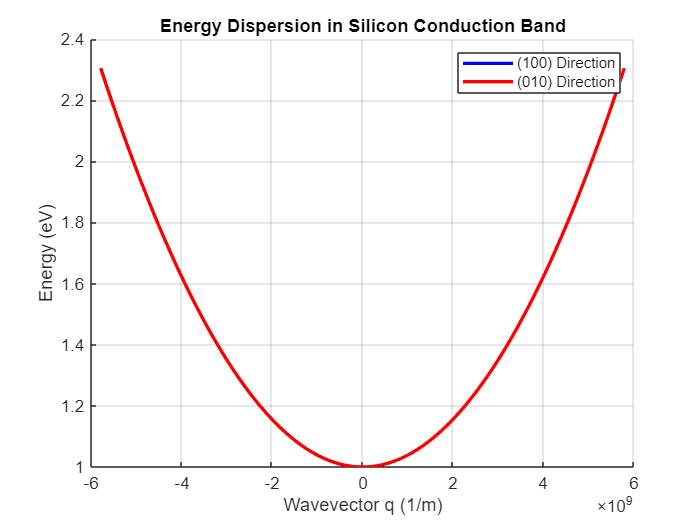

clc
clear
close all

a = 5.43e-10;           % Angstrom
L = 1e-9;               % 1 nm
e = 1.6e-19;            % C
n = 1;
e_c = e;                % 1 eV, for simplicity
h_bar = (6.626e-34) / (2 * pi);
m_o = 9.1e-31;          % mass of electron
m_l = 0.98 * m_o;
m_t = 0.19 * m_o;
m_z = m_l;              % z-direction effective mass
m_y = m_l;              % y-direction effective mass
m_x = m_l;              % x-direction effective mass

qx = linspace(-pi/a, pi/a, 100);  % x-space
qy = linspace(-pi/a, pi/a, 100);  % y-space

e_x = e_c + (h_bar^2 / 2) * (qx.^2 / m_x); % from (000) to (100)
e_y = e_c + (h_bar^2 / 2) * (qy.^2 / m_y); % from (000) to (010)

figure;
hold on;
plot(qx, e_x / e, 'b', 'LineWidth', 2);  % Energy along (100)
plot(qy, e_y / e, 'r', 'LineWidth', 2);  % Energy along (010)
xlabel('Wavevector q (1/m)');
ylabel('Energy (eV)');
title('Energy Dispersion in Silicon Conduction Band');
legend('(100) Direction', '(010) Direction');
grid on;
hold off;

These curves overlap each other, meaning they have the same energy

**c) **twofold degenerate (along z-direction)

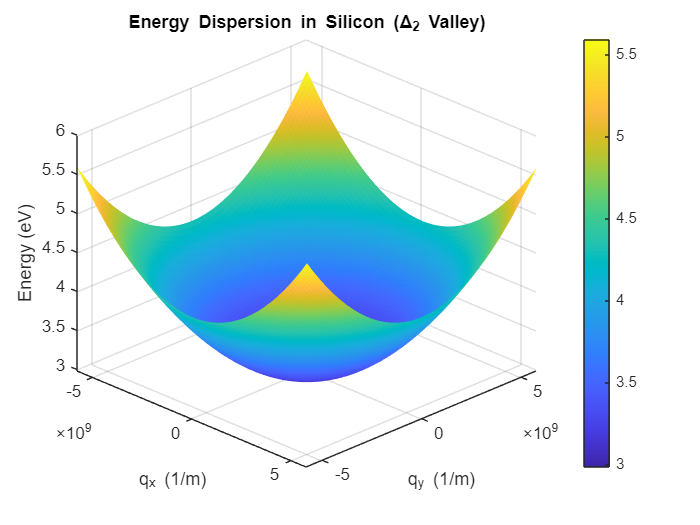

m_z = m_t;              % z-direction effective mass
m_y = m_l;              % y-direction effective mass
m_x = m_l;              % x-direction effective mass

[QX, QY] = meshgrid(qx, qy);

e_twofold = e_c + (h_bar^2 / 2) * ((QX.^2 / m_x) + (QY.^2 / m_y)) + (h_bar^2 / (2 * m_z)) * (n * pi / L)^2;
figure;
surf(QX, QY, e_twofold / e, 'EdgeColor', 'none');  % Smooth surface plot
xlabel('q_x (1/m)');
ylabel('q_y (1/m)');
zlabel('Energy (eV)');
title('Energy Dispersion in Silicon (\Delta_2 Valley)');
colorbar;
view(45, 30);  % Adjust view angle
grid on;

Since this is bounded in the z-direction, is is a 2D density of states (DOS), while the z-axis mass is $m_l$


$$m^*_{DOS} = \sqrt{m_1m_2} = \sqrt{m_xm_y} = \sqrt{m_tm_t} = m_t
$$



$$g_{2D} = \frac{m^*}{\pi\hbar^2} = \frac{m_t}{\pi\hbar^2}$$


g_2D_D2 = m_t / (pi * h_bar^2);
g_2D_D2 = g_2D_D2/ e;

**d) **fourfold degenerate (along x and y-direction)

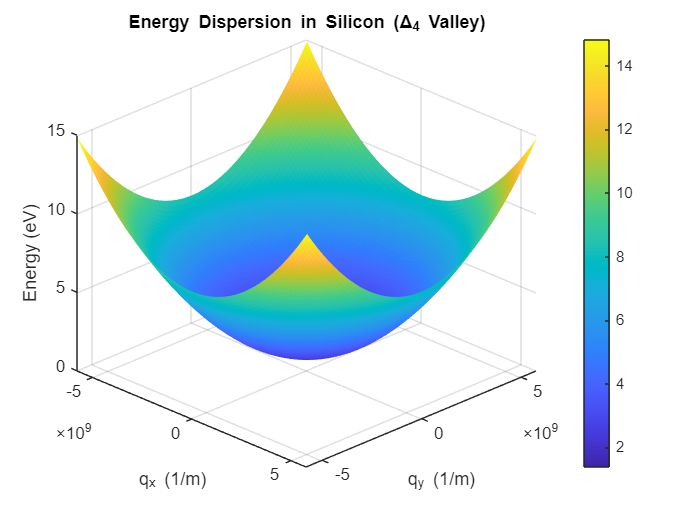

m_z = m_l;              % z-direction effective mass
m_y = m_t;              % y-direction effective mass
m_x = m_t;              % x-direction effective mass
e_fourfold = e_c + (h_bar^2 / 2) * ((QX.^2 / m_x) + (QY.^2 / m_y)) + (h_bar^2 / (2 * m_z)) * (n * pi / L)^2;
figure;
surf(QX, QY, e_fourfold / e, 'EdgeColor', 'none');  % Smooth surface plot
xlabel('q_x (1/m)');
ylabel('q_y (1/m)');
zlabel('Energy (eV)');
title('Energy Dispersion in Silicon (\Delta_4 Valley)');
colorbar;
view(45, 30);  % Adjust view angle
grid on;


$$m^*
_{DOS} = \sqrt{m_1m_2} = \sqrt{m_xm_y} = \sqrt{m_tm_l}

$$


for either x or y direction, that axes will be $m_t$, while the other will be $m_l$, so they will both have the same $m^*_{DOS}
$


$$g_{2D} = \frac{m^*}{\pi\hbar^2} = \frac{\sqrt{m_lm_t}}{\pi\hbar^2}$$


g_2D_D4 = sqrt(m_l * m_t) / (pi * h_bar^2);
g_2D_D4 = g_2D_D4 / e;

**e)** 

For each subgroup, n, there should be two steps. One for the twofold degeneracy and one for the fourfold.

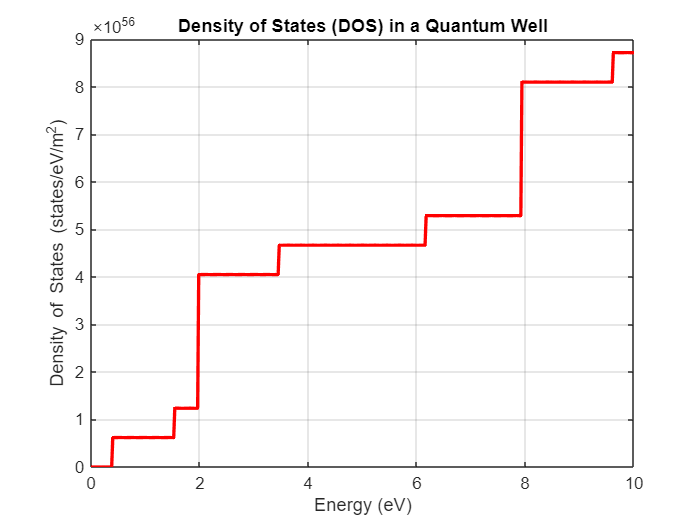

E_n_D2 = zeros(1, 5);
E_n_D4 = zeros(1, 5);

for n = 1:5         % calculating for the first 5 subbands
    E_n_D2(n) = (h_bar^2 / (2 * m_l)) * (n * pi / L)^2;
    E_n_D4(n) = (h_bar^2 / (2 * m_t)) * (n * pi / L)^2;
end

E = linspace(0, 10, 500) * e;  % Energy range from 0 to 0.5 eV
g_DOS_2D = zeros(size(E));

for n = 1:5
    for i = 1:length(E)
        if E(i) >= E_n_D2(n)
            g_DOS_2D(i) = g_DOS_2D(i) + 2 * g_2D_D2; % Add DOS for 2-fold valley
        end
        if E(i) >= E_n_D4(n)
            g_DOS_2D(i) = g_DOS_2D(i) + 4 * g_2D_D4; % Add DOS for 4-fold valley
        end
    end
end

% Plot the quasi-2D density of states
figure;
plot(E / e, g_DOS_2D, 'r', 'LineWidth', 2);
xlabel('Energy (eV)');
ylabel('Density of States (states/eV/m^2)');
title('Density of States (DOS) in a Quantum Well');
grid on;

## Problem 3

We are confined in both the y and z-direction, therefore, we can only calculate the energy dispersion relationship over momentum in the k-direction.

**c)**

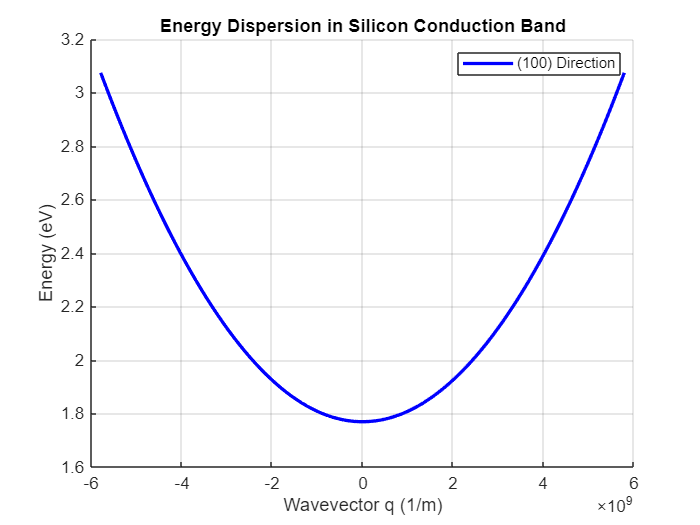

a = 5.43e-10;           % Angstrom
L_z = 1e-9;             % 1 nm
L_y = L_z;
e = 1.6e-19;            % C
n = 1;
e_c = e;                % 1 eV, for simplicity
h_bar = (6.626e-34) / (2 * pi);
m_o = 9.1e-31;          % mass of electron
m_l = 0.98 * m_o;
m_t = 0.19 * m_o;
m_z = m_l;              % z-direction effective mass
m_y = m_l;              % y-direction effective mass
m_x = m_l;              % x-direction effective mass
n_y = 1;
n_z = 1;

qx = linspace(-pi/a, pi/a, 100);  % x-space

e_x = e_c + (h_bar^2 / 2) * (qx.^2 / m_x) + (h_bar^2 / (2 * m_y)) * (n_y * pi / L_y)^2 + ...
    (h_bar^2 / (2 * m_z)) * (n_z * pi / L_z)^2;

figure;
hold on;
plot(qx, e_x / e, 'b', 'LineWidth', 2);  % Energy along (100)
xlabel('Wavevector q (1/m)');
ylabel('Energy (eV)');
title('Energy Dispersion in Silicon Conduction Band');
legend('(100) Direction');
grid on;
hold off;

**d)**

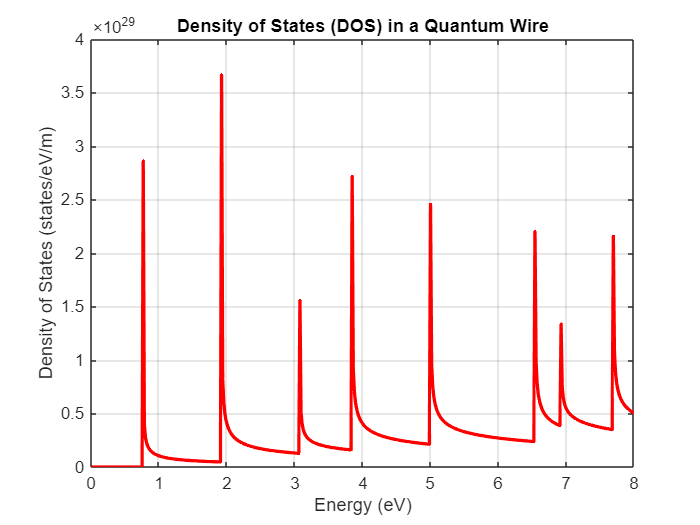

E = linspace(0, 8, 500) * e;  % Energy range from 0 to 0.5 eV
En = zeros(5, 5);

for n_y = 1:5
    for n_z = 1:5
        En(n_y, n_z) = (h_bar^2 / (2 * m_y)) * (n_y * pi / L_y)^2 + ...
                        (h_bar^2 / (2 * m_z)) * (n_z * pi / L_z)^2;
    end
end

g_DOS = zeros(size(E));

for n_y = 1:5
    for n_z = 1:5
        E_nyz = En(n_y, n_z);
        for i = 1:length(E)
            if E(i) >= E_nyz
                g_DOS(i) = g_DOS(i) + (1 / (pi * h_bar)) * sqrt(m_x / (2 * (E(i) - E_nyz)));
            end
        end
    end
end

g_DOS_1D = g_DOS / e;

% Plot the 1D density of states
figure;
plot(E / e, g_DOS, 'r', 'LineWidth', 2);
xlabel('Energy (eV)');
ylabel('Density of States (states/eV/m)');
title('Density of States (DOS) in a Quantum Wire');
grid on;

## Problem 4

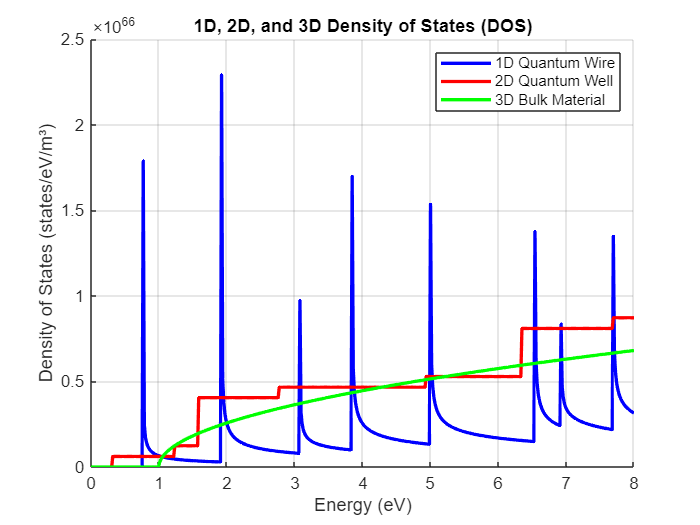

g_DOS_2D = g_DOS_2D / L_z;
g_DOS_1D = g_DOS_1D / L_z^2;

g_DOS_3D = zeros(size(E));
m_DOS = (m_l^3)^(1/3);          % not needed but still did it to show
                                % how the effective mass is obtained

for i = 1:length(E)
    if E(i) > e_c
        g_DOS_3D(i) = (1 / (2 * pi^2)) * ((2 * m_DOS / h_bar^2)^(3/2)) * sqrt(E(i) - e_c);
    end
end

g_DOS_3D = g_DOS_3D / e;

figure;
hold on;
plot(E / e, g_DOS_1D, 'b', 'LineWidth', 2); % 1D DOS (Quantum Wire)
plot(E / e, g_DOS_2D, 'r', 'LineWidth', 2); % 2D DOS (Quantum Well)
plot(E / e, g_DOS_3D, 'g', 'LineWidth', 2); % 3D DOS (Bulk Material)
xlabel('Energy (eV)');
ylabel('Density of States (states/eV/m³)');
title('1D, 2D, and 3D Density of States (DOS)');
legend('1D Quantum Wire', '2D Quantum Well', '3D Bulk Material');
grid on;
hold off;